 1. Write the Taylor expansion of a function s around the point x, as a function of the displacement h.


$$s(h) = \sum _{n=0}^\inf \frac{s^{(n)}(h)}{n!}(x-h)^n$$
    

2. For a fixed point x, explain how you can interpret the variation of s in a neighborhood around x as a linear combination of the functions 1, h, and h^2. What are the coefficients in the linear combination? Hint, see previous exercise

**The coefficients are {**$s(x), s'(x), s''(x)/2$**}**

3. At the end of Section 3, you are applying a set of three filters on the signal and then compute linear combinations (given by G−1) of the filter outputs to get the coordinates. What would happen if you did it the other way around, i.e., first form a linear combination of the filters (given by G−1) and then apply the resulting filters onto the signal?

**We want hm[k] to get the linear comb by multiplying with inv G but if we multiply with inv G to the filters fm[n] we will get multiplication of inv G m times for our hm[k].**

4. Given a symmetric 2 × 2 matrix G = [G11 G12; G12 G22], what is its inverse?


$$G^{-1} = \frac{1}{det(G)} [G_{22}, -G_{12}; -G{12}, G_{11}]$$


5. How does the uncertainty signal cert change the scalar product G0?

**The uncertainty signal makes the scalar product G0 position dependant. (slide 40, 2C) **$G_0[k] = diag(a[n]\cdot cert[k+n])$

6. Each element of the metric G is a scalar product between a specific combination of basis functions. If you look at element Gij = �bj |bi� of the metric, this is a function of the position along the signal. An efficient way of computing each Gij is in terms of a convolution between the certainty function and some function that only depends on the basis functions and the applicability. How?


$$G_{ij}[k] = \sum_nb_j[n] c[k+n]a[n]b_i^*[n]$$
 

**So just convolve the filter output **bj.*a.*bi **with certainty function for each i and j.**

7. In normalised averaging, described in Section 5, the filter derived from the basis fu    nction ”1” together with the applicability function is just the applicability function. Why?        

**Since we are just multiplying the applicability function with 1 for each point we get just the applicability function. We also flip the function but since a is symmetric it does not change.**

8. How do you compute the single element of the metric G in this case (normalised averaging)?  


$$G[k] = \sum_n a[-n]\cdot c[k+n]$$


**In other words just certainbility convolved with reversed a.**

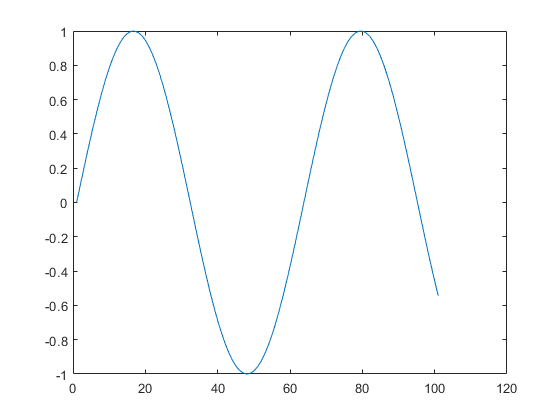

%sine
k = 0:1:100;
s = sin(k/10);
figure(1);plot(s);

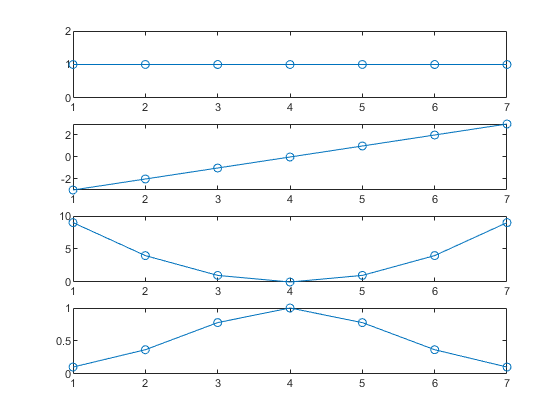


%x from -3 to 3 and basis 1 x x^2
x=(-3:3)';
b0=ones(7,1);
b1=x;
b2=x.^2;
figure(2);
subplot(4,1,1);plot(b0,'-o');
subplot(4,1,2);plot(b1,'-o');
subplot(4,1,3);plot(b2,'-o');

%applicability
a = exp(-x.^2/4);
figure(2);
subplot(4,1,4);plot(a,'-o');        

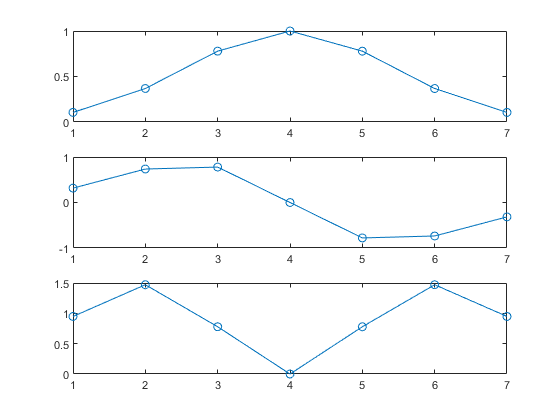


%mult basis with applicability and reverse order for filters
f0 = b0.*a; f0 = f0(end:-1:1);
f1 = b1.*a; f1 = f1(end:-1:1);
f2 = b2.*a; f2 = f2(end:-1:1);
figure(3);
subplot(3,1,1);plot(f0,'-o');
subplot(3,1,2);plot(f1,'-o');
subplot(3,1,3);plot(f2,'-o');


%convolve with filter
h0 = conv(s,f0,'same');
h1 = conv(s,f1,'same');
h2 = conv(s,f2,'same');

%basis
G0 = diag(a);
B = [b0 b1 b2]

B =      1    -3     9
     1    -2     4
     1    -1     1
     1     0     0
     1     1     1
     1     2     4
     1     3     9


G = B'*G0*B

G =     3.5042   -0.0000    6.3978
   -0.0000    6.3978    0.0000
    6.3978    0.0000   30.4044


QUESTION: Is the basis orthonormal?

**No since the base vectors are not length 1. The vectors are not orthogonal either.    **

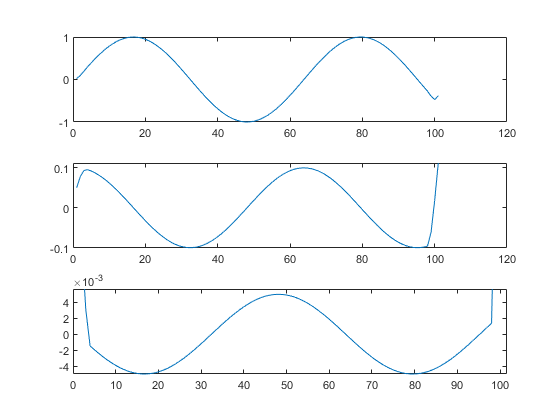

c = inv(G)*[h0;h1;h2];
figure(4);
subplot(3,1,1);plot(c(1,:))
subplot(3,1,2);plot(c(2,:))
subplot(3,1,3);plot(c(3,:))

QUESTION: The last three plots show the elements of the coordinate vector c. Are they as expected? Hint: poly    nomial expansion is related to a Taylor expansion of a function, as described in preparatory exercise 2. In what way?

**Since the first one should just be the original signal it looks right. The second one should be the first derivative which should be 1/10*cos(1/10*x) which looks correct disregarding the edges where derivative isn't well defined. The third should be -1/2*1/10^2*sine(1/10x) which looks correct once again disregarding edges.**

**at the edges the signal tries to go back to 0 which explains the edge artifacts.**

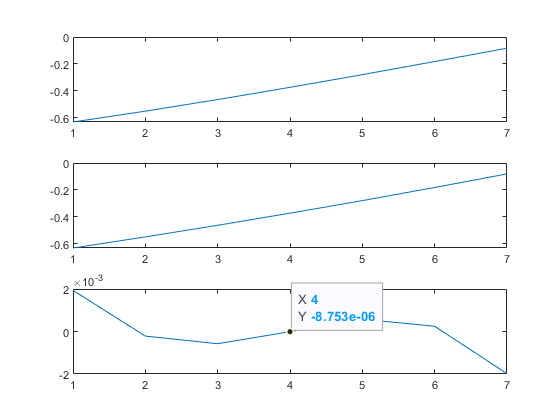

figure(5);
localsig=s(60-3:60+3);
reconsig=(B*c(:,60))';
diffsig=localsig-reconsig;
subplot(3,1,1);plot(localsig);
subplot(3,1,2);plot(reconsig);
subplot(3,1,3);plot(diffsig);   

QUESTION: Is the reconstructed signal very different or very similar to the local signal? Explain why.

**The reconstructed signal here is very similar to the local signal, at least around the middle. This is obvious when looking at the applicability signal that is a gaussian with value 1 at the middle. Taylor is also best at the point where we observe. We also see that error is a 3rd degree function since we only use up to 2nd degree in our expansion.**

**tokens:**

**9GNP-1II4**

**5WZB-5BST**

***4. Uncertain Data***

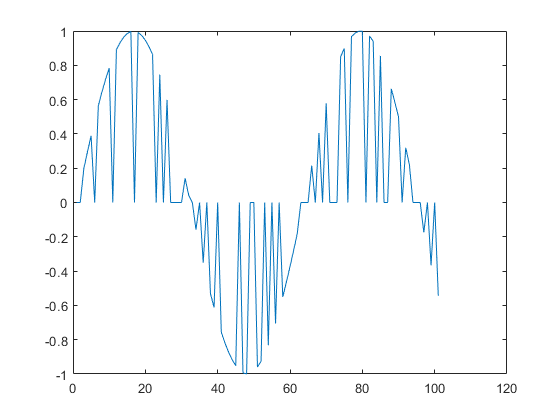

cert = double(rand(1,101)>0.4);
scert = s.*cert;
figure(6);plot(scert);

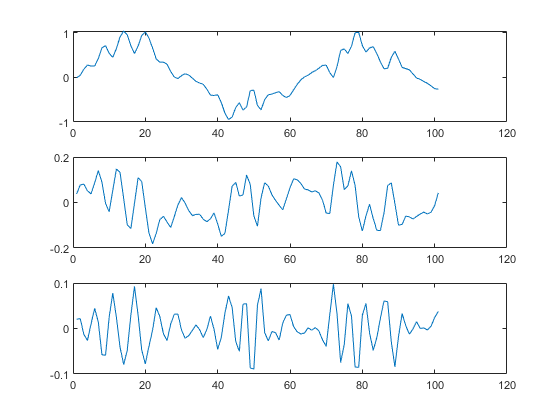


%convolve scert with filters
h02 = conv(scert,f0,'same');
h12 = conv(scert,f1,'same');
h22 = conv(scert,f2,'same');

%get coordinates
c2 = inv(G)*[h02;h12;h22];
figure(7);
subplot(3,1,1);plot(c2(1,:))
subplot(3,1,2);plot(c2(2,:))
subplot(3,1,3);plot(c2(3,:))

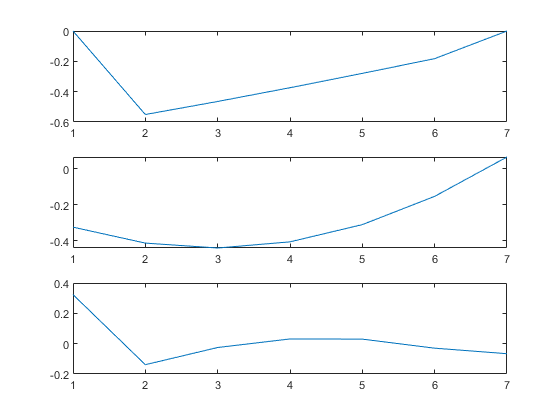


%expanding
figure(8);
localsig2=scert(60-3:60+3);
reconsig2=(B*c2(:,60))';
diffsig2=localsig2-reconsig2;
subplot(3,1,1);plot(localsig2);
subplot(3,1,2);plot(reconsig2);
subplot(3,1,3);plot(diffsig2);

QUESTION: In what way do the results change? Explain why.

**Due to the missing data the first function of 1 still resembles a sine but with a lot of bumps and valleys that affect the derivatives drastically. Taking the linear combinations of these no longer give a good reconstruction without considering the uncertainty.**

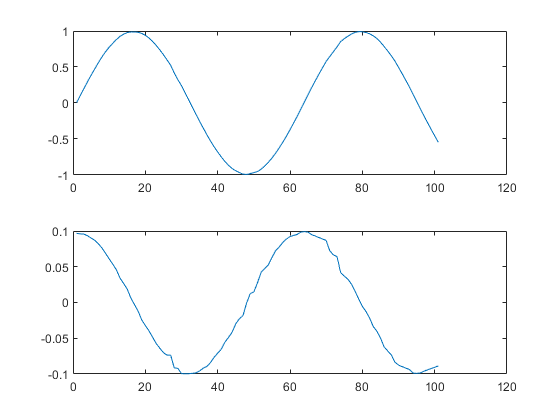

h0 = conv(scert,f0,'same');
h1 = conv(scert,f1,'same');

%mult basis with applicability and reverse order(prep ex 6)
f11 = b0.*a.*b0; f11 = f11(end:-1:1);
f12 = b0.*a.*b1; f12 = f12(end:-1:1);
f22 = b1.*a.*b1; f22 = f22(end:-1:1);

%convolve
G11 = conv(cert,f11,'same');
G12 = conv(cert,f12,'same');
G22 = conv(cert,f22,'same');

%transform dual coords into proper coords
detG = G11.*G22-G12.^2;
c0 = (G22.*h0-G12.*h1)./detG;
c1 = (-G12.*h0+G11.*h1)./detG; figure(9);   
subplot(2,1,1);plot(c0)
subplot(2,1,2);plot(c1)

QUESTION: How do you interpret the computations that are made for c0 and c1?

**It is just the inverse of G times the filter responses **

QUESTION: Compare this result, (c0, c1), to the previous one where the certainty function was not taken into account. What it is the difference?

**It is smooth and correct even at the edges although not a perfect reconstruction.**

QUESTION: The signals c0 and c1 should not exhibit any border effects. In the previous task you did get border effects when you computed coordinates c0 and c1 (see figure 4). Explain this observation.

**Since we are now considering where the signal is valid and where it is not we will not consider signal values outside of our specified range so we do not get the same border effects.**

QUESTION: Modify the signal by removing a higher rate of the samples (e.g. 50%) and see how this changes the result. How large rate of samples can be removed without too much distortion in the measured coordinates (c0, c1)?

**About 40%**

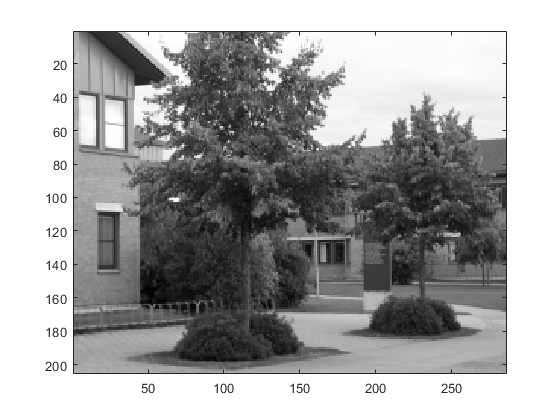

%read im
im = double(imread('Scalespace0.png'));
figure(10);colormap(gray);imagesc(im);

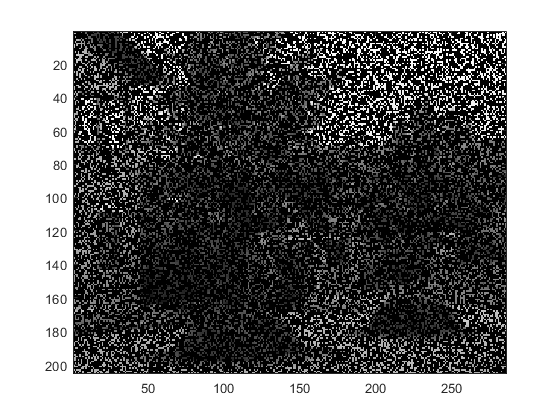


%remove parts
cert = double(rand(size(im)) > 0.7 ); imcert = im.*cert;
figure(11);colormap(gray);imagesc(imcert);

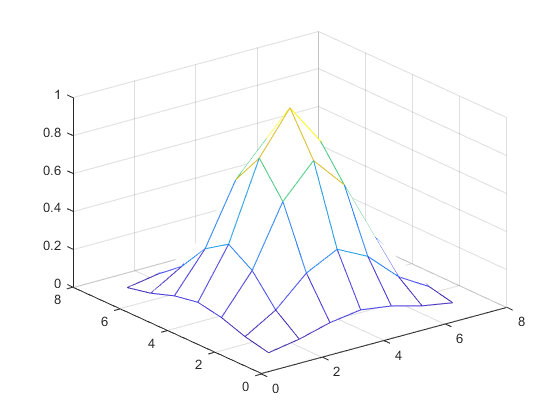


%applicability func
x = ones(111,1)*(-55:55);
x = ones(7,1)*(-3:3);
%x = ones(3,1)*(-1:1)
y = x';
a = exp(-(x.^2+y.^2)/4);
figure(12);mesh(a);

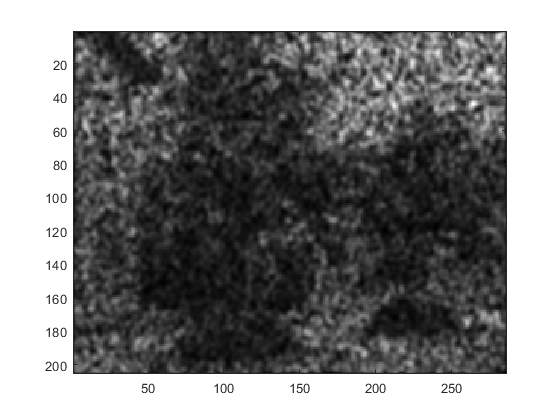


%convolve with applicability
imlp = conv2(imcert, a, 'same');
figure(13);colormap(gray);imagesc(imlp);

QUESTION: Did this solve the problem of missing pixels? Explain why.

**No, we are just convolving with a low pass filter. Just like the 1D case we need to know something about the certainty of the signal.**

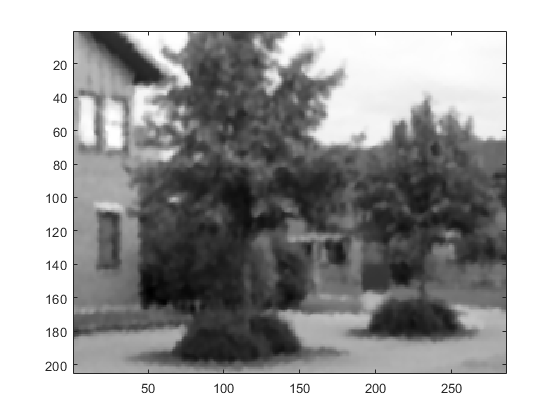

%convolve like in prep 8, a is symmetrical so no need to reverse
G = conv2(cert, a, 'same');
c = imlp./G;
figure(14);colormap(gray);imagesc(c);

QUESTION: Is this result better than before? Explain why?

**Yes, since we now know the certainty function we can somewhat reconstruct it just like how we did in the 1D case. This is because we do not get a bunch of distortions in our basis function coordinates.**

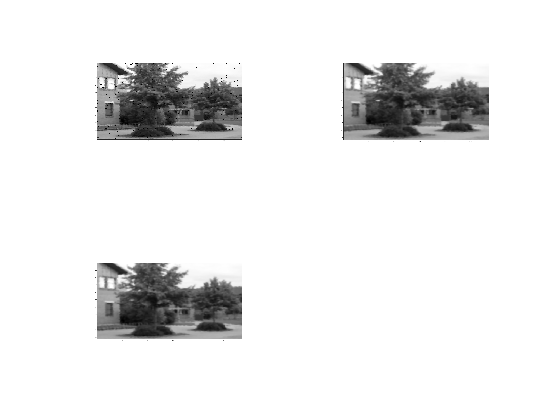


figure(15)
subplot(2,2,1)
imshow("xw3.png")
subplot(2,2,2)
imshow("xw7.png")
subplot(2,2,3)
imshow("xw111.png")

QUESTION: Change the width of the applicability function to smaller or larger values. What happens?

**For larger widths there is more smudging while for lower some signals might still be black but the picture is sharper.**

QUESTION: Increase the number of missing pixels. How large percentage can be removed until you cannot see the picture in the reconstructed image?

**At over ~95% the picture starts to become unrecognizeable.**

QUESTION: Remove 90% of the pixels and reconstruct the image by means of normalised averaging. There will be a few pixels of random positions in the result that are black and if you investigate their value it is Not-A-Number. Explain why.

**This usually means we are dividing by 0 somewhere. Most likely there will be 0s in G since there are areas of 0 in cert that are larger than size of 'a' so it will turn out to 0 that we then use to divide at row 115.**

QUESTION: How would you do to further improve the result?

**Make a wider.**

QUESTION: How did you do it? Do you succeed?

**Using x width 111 the NaN are removed but the image is quite smudged.**

**tokens:**

**9GNP-1II4**

**5WZB-5BST**

**BAQX-TZ9O**

**OVBM-QM4W**